Main file

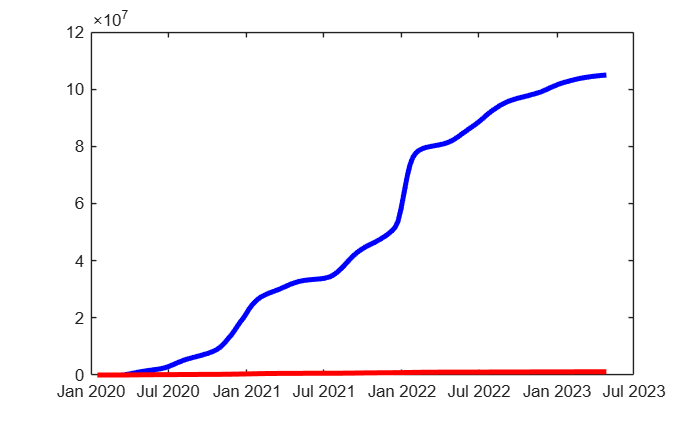

bad_tab_data = readtable("Weekly_United_States_COVID-19_Cases_and_Deaths_by_State_-_ARCHIVED_20261001.csv", "Delimiter", ",");
tab_data = sortrows(bad_tab_data, 1);

badWeekData = tab_data.start_date;
badInfectedData = tab_data.tot_cases;
badDeathsData = tab_data.tot_deaths;
badInfectedData2 = tab_data.new_cases;
badDeathsData2 = tab_data.new_deaths;
weekData = [];
weekData2 = [];
infectedData = [];
deathsData = [];
infectedData2 = [];
deathsData2 = [];


for i= 1 : 60: length(badWeekData) - 60
    weekData = [weekData, badWeekData(i)];
    infectedData = [infectedData, sum(badInfectedData(i:i+60))];
    deathsData = [deathsData, sum(badDeathsData(i:i+60))];
end

figure()
plot(weekData, infectedData, 'b', 'LineWidth', 3, 'DisplayName', 'Infected'); hold on
plot(weekData, deathsData, 'r', 'LineWidth', 3, 'DisplayName', 'Dead')
hold off;

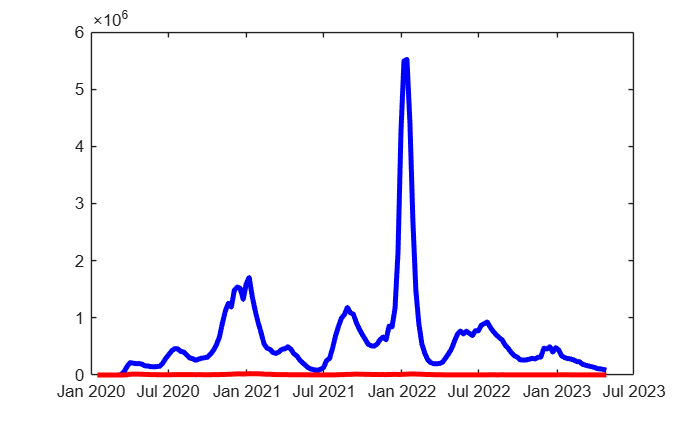


for i= 1 : 60: length(badWeekData) - 60
    weekData2 = [weekData2, badWeekData(i)];
    infectedData2 = [infectedData2, sum(badInfectedData2(i:i+60))];
    deathsData2 = [deathsData2, sum(badDeathsData2(i:i+60))];
end

figure()
plot(weekData2, infectedData2, 'b', 'LineWidth', 3, 'DisplayName', 'Infected'); hold on
plot(weekData2, deathsData2, 'r', 'LineWidth', 3, 'DisplayName', 'Dead')
hold off;

%found from paper or csv
Pcontact = 0.5;
Pinfectivity_semirisk = 0.0132;
Pinfectivity_risk = 0.27;
Precovered = 0.9965/7;
Pdeceased = 0.0035/7;
Pvaccinated = 0.0033;

numPostInfection = 19000000;
numVaccinated = 0;
numNaive = 258141000;
numInfectious = 1155000;
numDeceased = 0;
% numPostInfection = 3700000;
% numVaccinated = 0;
% numNaive = 50378000;
% numInfectious = 225000;
% numDeceased = 0;

young_people = Subpopulation(Pcontact, Pinfectivity_semirisk, Pinfectivity_risk, ...
                                     Precovered, Pdeceased, Pvaccinated, ...
                                     numPostInfection, numVaccinated, numNaive, ...
                                     numInfectious, numDeceased);

Pcontact = 0.5;
Pinfectivity_semirisk = 0.0414;
Pinfectivity_risk = 0.27;
Precovered = 0.911/7;
Pdeceased = 0.089/7;
Pvaccinated = 0.0033;

numPostInfection = 3700000;
numVaccinated = 0;
numNaive = 50378000;
numInfectious = 225000;
numDeceased = 0;

old_people = Subpopulation(Pcontact, Pinfectivity_semirisk, Pinfectivity_risk, ...
    Precovered, Pdeceased, Pvaccinated, ...
    numPostInfection, numVaccinated, numNaive, ...
    numInfectious, numDeceased);

PInfect1Contact2 = 0.5;
PInfect2Contact1 = 0.2;

model = COVIDModel(young_people, old_people, PInfect1Contact2, PInfect2Contact1);

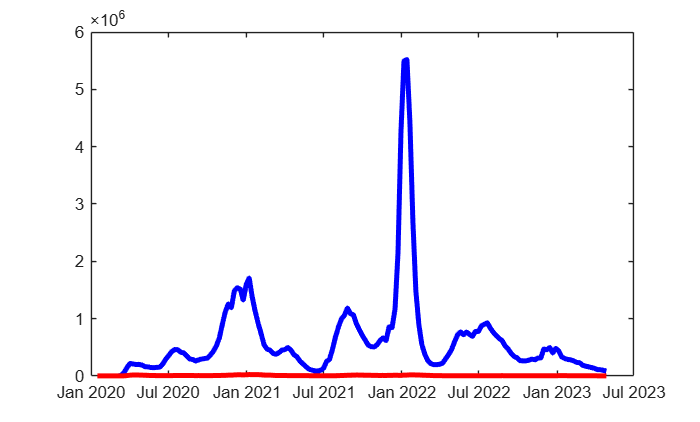

hold off;

days = 7*26;

infected1 = zeros(1,days);
infected2 = zeros(1,days);
deceased1 = zeros(1,days);
deceased2 = zeros(1,days);

infected1(1) = young_people.numInfectious;
infected2(1) = old_people.numInfectious

infected2 =       225000           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


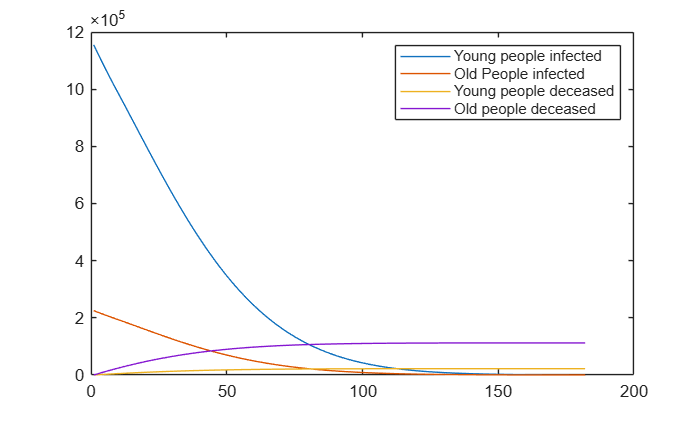

infected = [];
deceased = [];
for day = 2:days
    total_people = model.getPopulation();
    model.simulateAction(day);
    
    infected1(day) = model.subpopulation1.numInfectious;
    infected2(day) = model.subpopulation2.numInfectious;
    deceased1(day) = model.subpopulation1.numDeceased;
    deceased2(day) = model.subpopulation2.numDeceased;

    % infected = [infected, model.subpopulation1.numInfectious + model.subpopulation2.numInfectious];
    % deceased = [deceased, model.subpopulation1.numDeceased + model.subpopulation2.numDeceased];
     
    assert(abs(total_people - model.getPopulation()) < 1e-3, "Total population changes on day: " + day + ". Calculated: " + model.getPopulation() + ". Expected: " + total_people);
    assert(young_people.numNaive >= 0 && old_people.numNaive >= 0) 
end

plot(1:days, infected1);
hold on;
plot(1:days, infected2);
hold on;
plot(1:days, deceased1);
hold on;
plot(1:days, deceased2);
legend("Young people infected", "Old People infected", "Young people deceased", "Old people deceased")

weekly = groupsummary(tab_data, "start_date", "sum", "new_cases");
startIdx = find(weekly.start_date == datetime(2021,1,21));
nWeeks = floor(days/7);
dataWeeks = weekly.start_date(startIdx : startIdx+nWeeks-1);
dataCases = weekly.sum_new_cases(startIdx : startIdx+nWeeks-1);

modelCases = infected1(7:7:7*(nWeeks)) + infected2(7:7:7*(nWeeks));
size(modelCases)

ans =      1    26


size(dataWeeks)

ans =     26     1


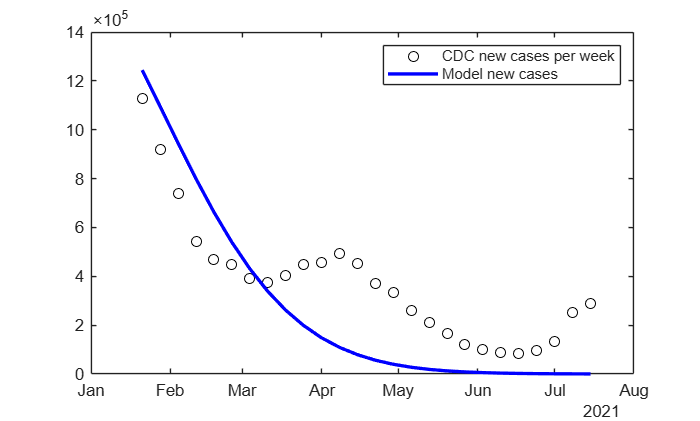

% 1 2 3 4 5 6 
figure()
plot(dataWeeks, dataCases, 'ko', 'DisplayName', 'CDC new cases per week'); hold on
plot(dataWeeks, modelCases, 'b', 'LineWidth', 2, 'DisplayName', 'Model new cases'); hold off
legend